# Finite Difference Method - 1D Poisson Equation

Use the FDM to solve Poisson's equation for $x \in [a,b]$

## Step 1: Dirichlet BCs


$$    \left\{
     \begin{array}{c}
          \frac{\mathrm{d^2}\varphi}{\mathrm{d}x^2} - t(x)= 0 \\
         \varphi(a) = \varphi_a\\
         \varphi(b) = \varphi_b\\
       \end{array}$$


Create an m-function "FDM_1D_s1" with the following I/O scheme:

- input: geometry (a, b, number of nodes); boundary conditions (boundary condition type and value in a and b); uniform source term $t(x)=t$

- output: x (coordinates of nodes), phi (computed values of uknown function)

Use the function to simulate a case where $a = 0; b = 1; n = 11; \varphi_a = 1; \varphi_b = 0; t = 0
$.

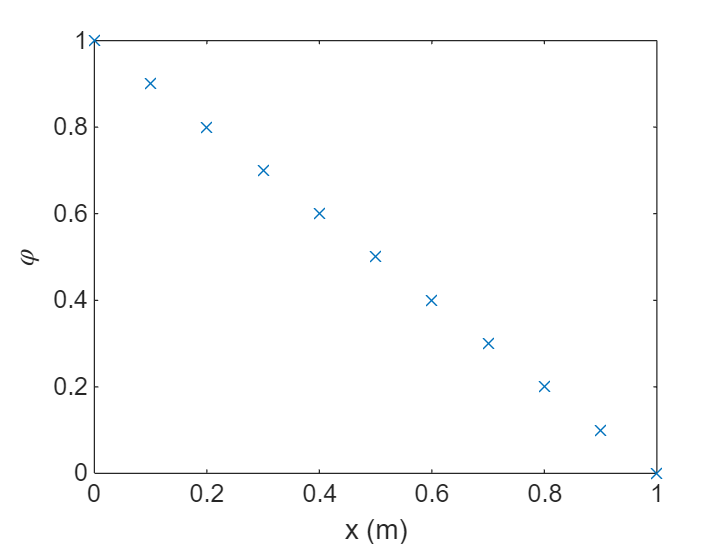

clear variables
clc

geom.a = 0;
geom.b = 1;
geom.n = 11; % this is a comment

BC.a.type = 'D'; % Dirichelt
BC.a.val = 1;
BC.b.type = 'D';
BC.b.val = 0;

t = 0; % zero source term

[x,phi] = FDM_1D_s1(geom,BC,t);

plot(x,phi,'x');
xlabel('x (m)')
ylabel('$\varphi$','Interpreter','latex')

Set t = 5 and check with exact solution


$$    \varphi(x) = \frac{t}{2} x^2 + \left( \frac{\varphi_b - \varphi_a - \frac{t}{2} L^2}{L} \right)x + \varphi_a$$


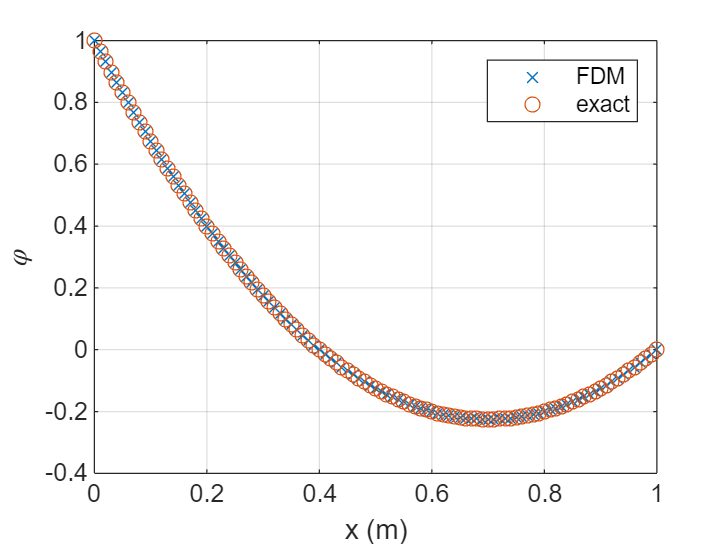

geom.n = 101; % increase number of nodes
t = 5; % non-zero source term

[x,phi] = FDM_1D_s1(geom,BC,t);

% analytical expression
L = geom.b-geom.a;
phi_exact = t/2*x.^2 + ((BC.b.val-BC.a.val-t/2*L^2)/L).*x+BC.a.val;

plot(x,phi,'x',x,phi_exact,'o'); % plotting numerical and analytical solution
xlabel('x (m)')
ylabel('$\varphi$','Interpreter','latex')
legend('FDM','exact')
grid on

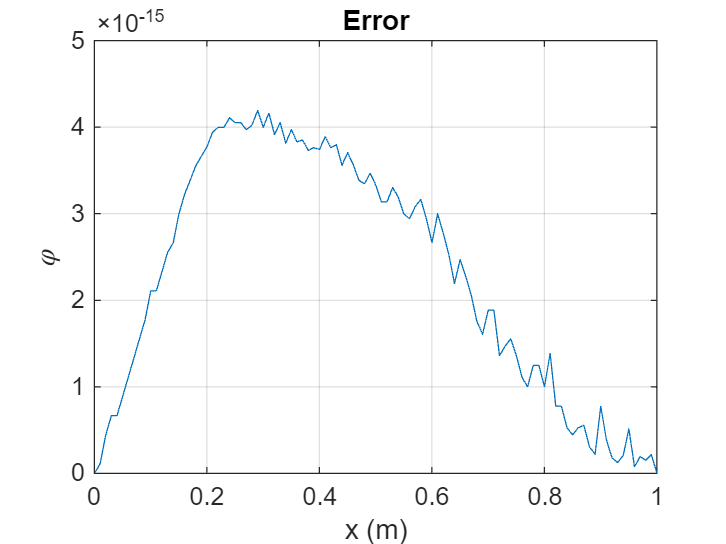


% compute absolute error
plot(x,abs(phi-phi_exact')); % absolute error
xlabel('x (m)')
ylabel('$\varphi$','Interpreter','latex')
grid on
title('Error')

Compare the solutions obtained by setting $t=0
$ and $t = 10$.

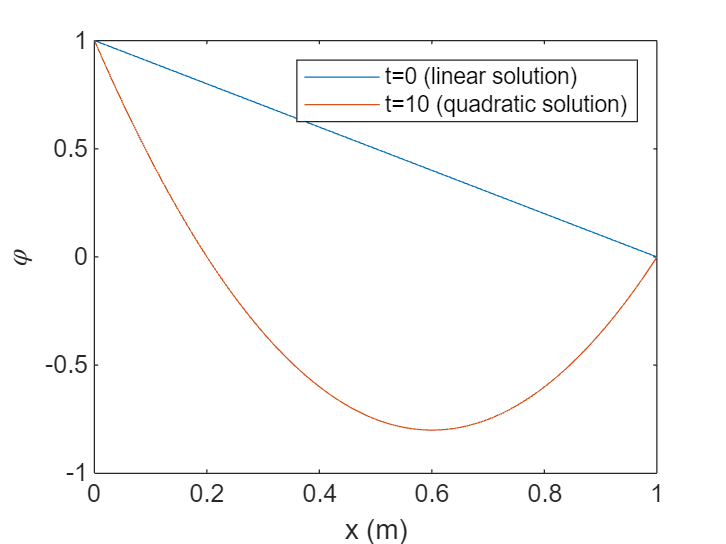

t = 0;
[x,phi_0] = FDM_1D_s1(geom,BC,t);

t = 10;
[x,phi_10] = FDM_1D_s1(geom,BC,t);

plot(x,phi_0,x,phi_10)
legend('t=0 (linear solution)','t=10 (quadratic solution)')
xlabel('x (m)')
ylabel('$\varphi$','Interpreter','latex')

Implement non-uniform t

t = @(x) 1/x; % linear source term

geom.n = 11; % coarse grid
[x_coarse,phi_coarse] = FDM_1D_s2(geom,BC,t);

geom.n = 101; % fine grid
[x_fine,phi_fine] = FDM_1D_s2(geom,BC,t);

geom.n = 1001; % fine(r) grid
[x_finer,phi_finer] = FDM_1D_s2(geom,BC,t);

plot(x_coarse,phi_coarse,...
    x_fine,phi_fine,...
    x_finer,phi_finer)
xlabel('x (m)')
ylabel('$\varphi$','Interpreter','latex')
str = {'11 nodes','101 nodes','1001 nodes'}

str = 1×3 cell array
    {'11 nodes'}    {'101 nodes'}    {'1001 nodes'}


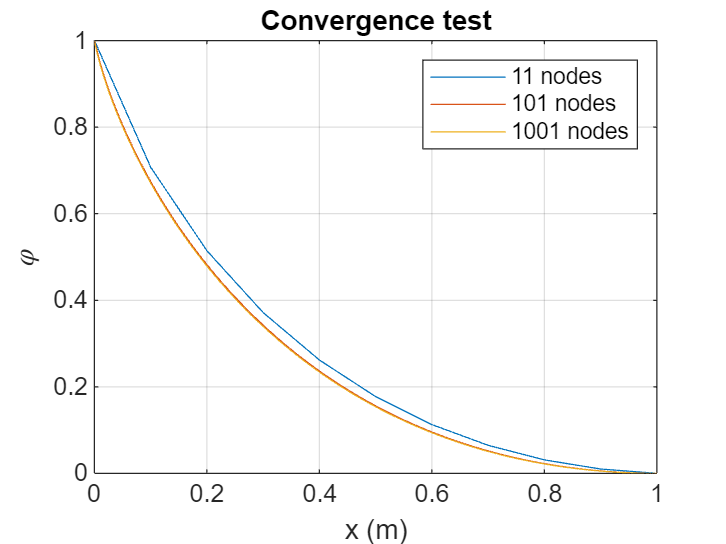

legend(str)
grid on
title('Convergence test')

## Step 2: Dirichlet and Neumann BCs

Implement Neumann conditions and use it to simulate a half-domain with a zero Neumann BC on one side.


$$    \left\{
     \begin{array}{c}
          \frac{\mathrm{d^2}\varphi}{\mathrm{d}x^2} - t(x)= 0 \\
         \varphi(a) = \varphi_a\\
         \left.\frac{\mathrm{d}\varphi}{\mathrm{d}x}\right|_{x=b}=\varphi'_b
       \end{array}$$


For node n:


$$\varphi_{n-1}-\varphi_{n}=\frac{t_{n}}{2}\Delta x^2-\Delta x \varphi_b'$$


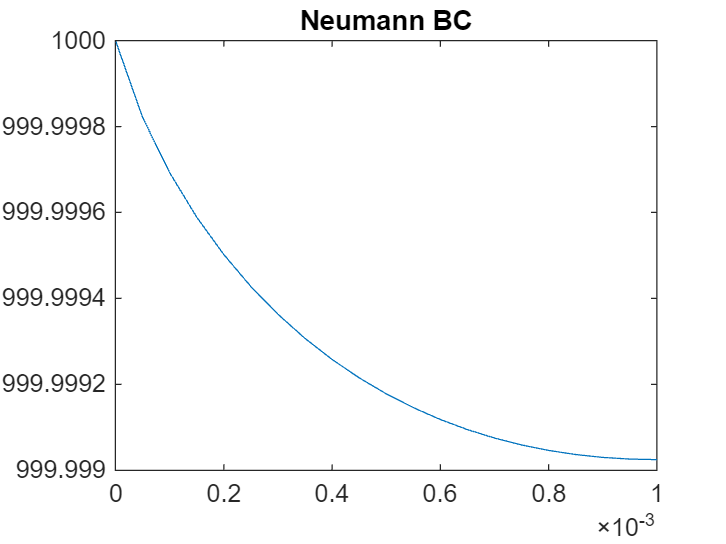

BC.b.type = 'N'; % Neumann
BC.b.val = 0;

t = @(x) 1/x;

geom.n = 21; % coarse grid
[x,phi] = FDM_1D_s2(geom,BC,t);

plot(x,phi)
title('Neumann BC')

Compare it with a symmetrical Dirichlet condition on a corresponding full domain.

t = @(x) -5;

BC.a.type = 'D';
BC.a.val = 0;
BC.b.type = 'N'; % Neumann
BC.b.val = 0;
geom.b = 0.5; % half-domain
geom.n = 11; % coarse grid
[x_N,phi_N] = FDM_1D_s2(geom,BC,t);

BC.a.type = 'D';
BC.a.val = 0;
BC.b.type = 'D'; % Dirichlet
BC.b.val = 0;
geom.b = 1; % full domain
geom.n = 21; % coarse grid
[x_D,phi_D] = FDM_1D_s2(geom,BC,t);

plot(x_N,phi_N,'x',x_D,phi_D)
title('Neumann BC')
legend('Neumann','Dirichlet')

## Step 3: Use the code to compute the electric field between two charged plates with/without space charge

1 KV between parallel plates 1 mm apart, in absence of space charge

close all % clear all figures

BC.a.type = 'D';
BC.a.val = 1000; % 1000 V
BC.b.type = 'D';
BC.b.val = 0; % 0 V
geom.b = 1E-3; % 1 mm
geom.n = 11; % coarse grid
t = @(x) 0;
[x,phi] = FDM_1D_s2(geom,BC,t);

dphi_dx = zeros(geom.n,1);
dx = (geom.b-geom.a)/(geom.n-1); % grid spacing

% loop-based version
%{
dphi_dx(1) = (phi(2)-phi(1)) / dx; % 1st order FWD 
for k=2:geom.n-1
    dphi_dx(k) = (phi(k+1)-phi(k-1)) / (2*dx);
end
dphi_dx(end) = (phi(end)-phi(end-1)) / dx; % 1st order BWD 
%}

% vectorized version
dphi_dx(1) = (phi(2)-phi(1)) / dx; % 1st order FWD 
dphi_dx(2:end-1) = (phi(3:end)-phi(1:end-2)) / (2*dx);
dphi_dx(end) = (phi(end)-phi(end-1)) / dx; % 1st order BWD 

E = -dphi_dx;

yyaxis left
plot(x,phi,'x')
ylabel('Electric potential (V)');
yyaxis right
plot(x,E,'o')
ylabel('Electric field (V/m)')
xlabel('gap length (m)')

...in presence of space charge

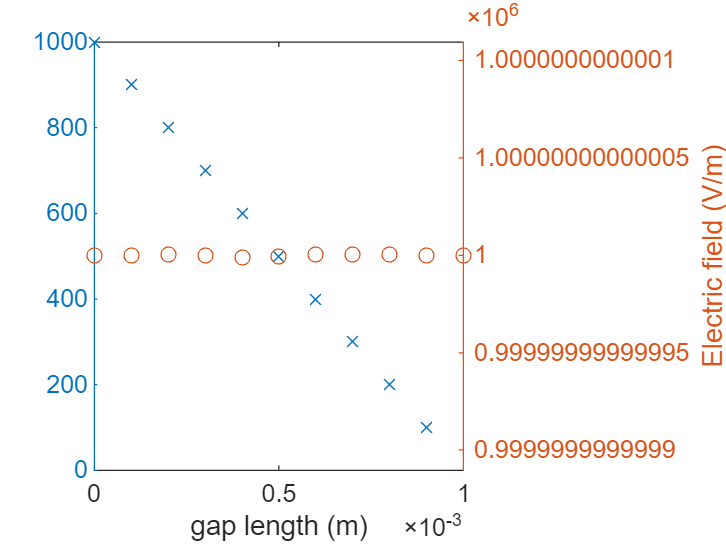

BC.a.type = 'D';
BC.a.val = 1000; % 1000 V
BC.b.type = 'D';
BC.b.val = 0; % 0 V
geom.b = 1E-3; % 1 mm
geom.n = 11; % coarse grid

t = @(x) -1E9; % t = -rho/epsilon_0
[x,phi] = FDM_1D_s2(geom,BC,t);

dphi_dx = zeros(geom.n,1);
dx = (geom.b-geom.a)/(geom.n-1); % grid spacing

% vectorized version
dphi_dx(1) = (phi(2)-phi(1)) / dx; % 1st order FWD 
dphi_dx(2:end-1) = (phi(3:end)-phi(1:end-2)) / (2*dx);
dphi_dx(end) = (phi(end)-phi(end-1)) / dx; % 1st order BWD 
E = -dphi_dx; % electric field - first-order

% vectorized version - second-order
dphi_dx(1) = (-3*phi(1)+4*phi(2)-phi(3)) / (2*dx); % 2st order FWD 
dphi_dx(2:end-1) = (phi(3:end)-phi(1:end-2)) / (2*dx);
dphi_dx(end) = (3*phi(end)-4*phi(end-1)+phi(end-2)) / (2*dx); % 2st order BWD 
E2 = -dphi_dx; % electric field - second-order

yyaxis left
plot(x,phi,'x')

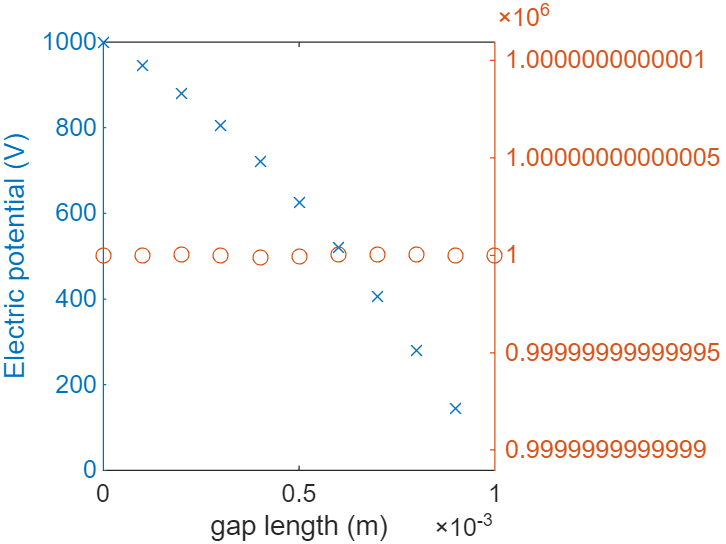

ylabel('Electric potential (V)');
yyaxis right
plot(x,E,'-o',x,E2,'--o')

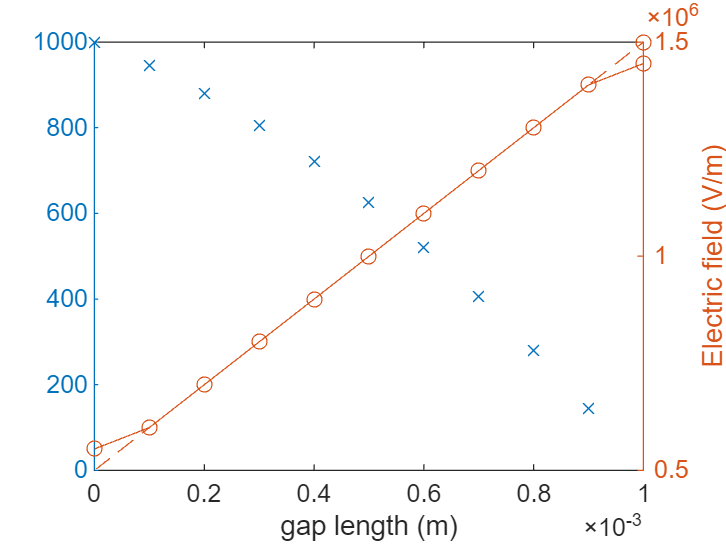

ylabel('Electric field (V/m)')
xlabel('gap length (m)')

E = -dphi_dx;

yyaxis left
plot(x,phi,'x')

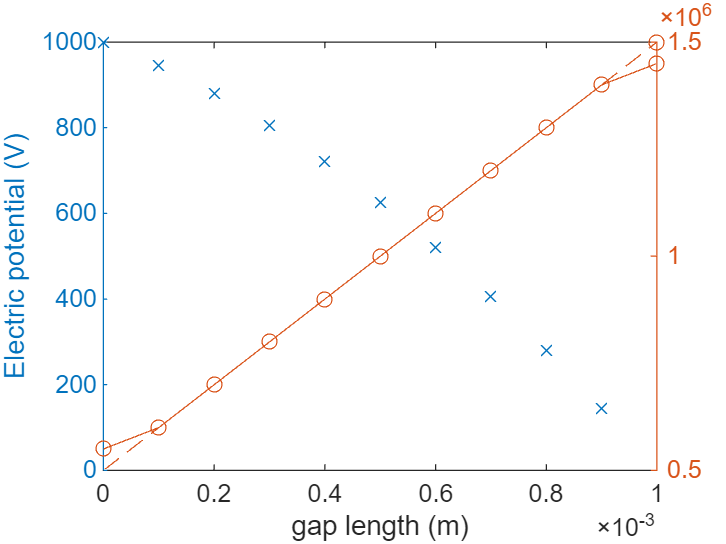

ylabel('Electric potential (V)');
yyaxis right
plot(x,E,'-o')

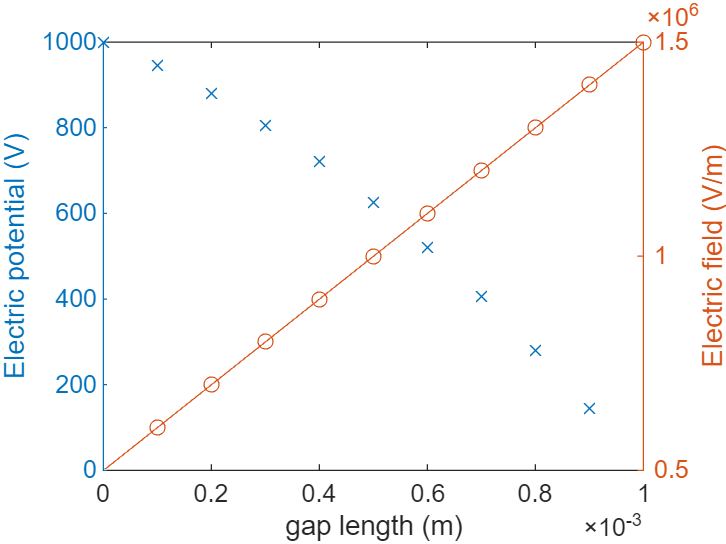

ylabel('Electric field (V/m)')
xlabel('gap length (m)')